# The Multi-Point Correlation Function in Non-stationary States

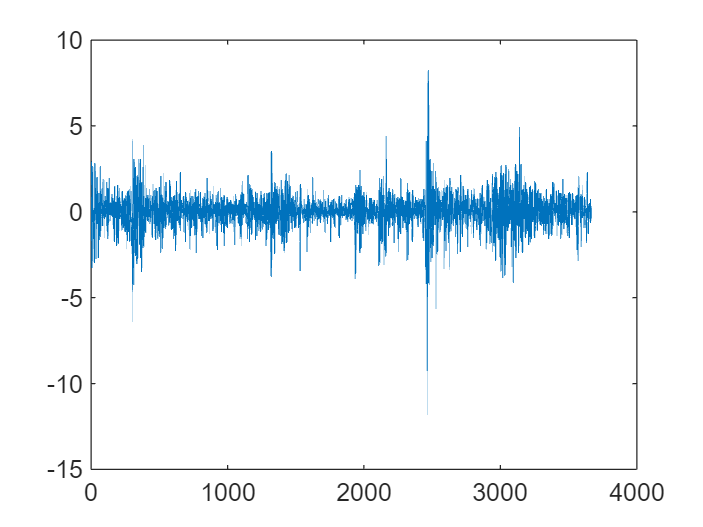

clear
load('index_2010_2024.mat');
P = SP500.price(100:end); % SSE.price(487:end) 2012-2024;SP500.price(505:end) 2012-2024
R = diff(log(P));
r = zscore(R);

% For convenience, standardize the input time series to column vector format.
if size(r,1) < size(r,2)
    r = r'; 
end
B = r; 

% A may represent either an internal driving force, such as dynamic fluctuations in various systems, 
% or an external one, such as external information in complex financial systems.
A = abs(r);

figure()
plot(B)

## Parameter setting

% This case examines the volatility-return correlation, 
% specifically the influence of intrinsic drivers on dynamic variables. 
% The following parameter settings are provided, which can be adjusted based on specific requirements.
T_para = [5,1,44,45,5,400]; % Parameters for time window traversal
tc = 100; % Length of two-point correlation function
tg = 20; % Length of multi-point correlation function
Q = 1; % Intrinsic drivers

## Optimal time window selection for multi-point correlation

[AP0_mp,Am_mp,num_mp,T_opt_mp,Tb_opt_mp] = window_selection_MP_func(A,B,Q,T_para,tg);

[Am_mp,num_mp,T_opt_mp,Tb_opt_mp]

ans =      0.018833          159           33          160


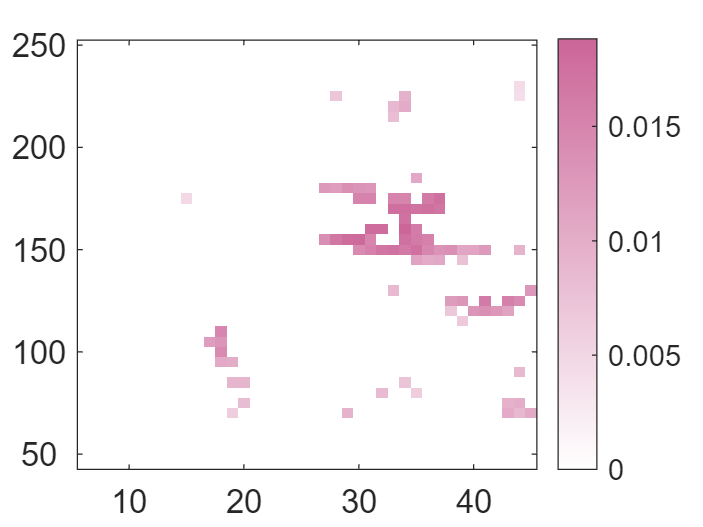

for Tb = 45:5:400
    AP0_plot2(:,(Tb-40)/5) = AP0_mp(5:end,Tb);
    FAP02 = (AP0_plot2)';
end

target_color = [0.8, 0.4, 0.6]; 
n_colors = 256; 
custom_colormap = [linspace(1, target_color(1), n_colors);
                   linspace(1, target_color(2), n_colors); 
                   linspace(1, target_color(3), n_colors)]';  
fontsize = 13;
% figure()
% imagesc(FAP02); 
% set(gca,'xtick',5:10:44,'xticklabel',10:10:40);
% set(gca,'ytick',2:10:72,'yticklabel',50:50:400);
% set(gca,'YDir','normal');
figure()
imagesc(FAP02(1:42,:)); 
set(gca,'xtick',5:10:44,'xticklabel',10:10:40);
set(gca,'ytick',2:10:42,'yticklabel',50:50:250);
set(gca,'YDir','normal'); 
colormap(custom_colormap);
c = colorbar;
c.FontSize = fontsize;
c.Limits = [0, 0.02];
c.Ticks = [0:0.005:0.02]; 
% xlabel('$T$','Interpreter','latex')
% ylabel('$T_b$','Interpreter','latex','Rotation',0)
set(gca, fontsize=fontsize)

## The multi-point correlation under the optimal time window

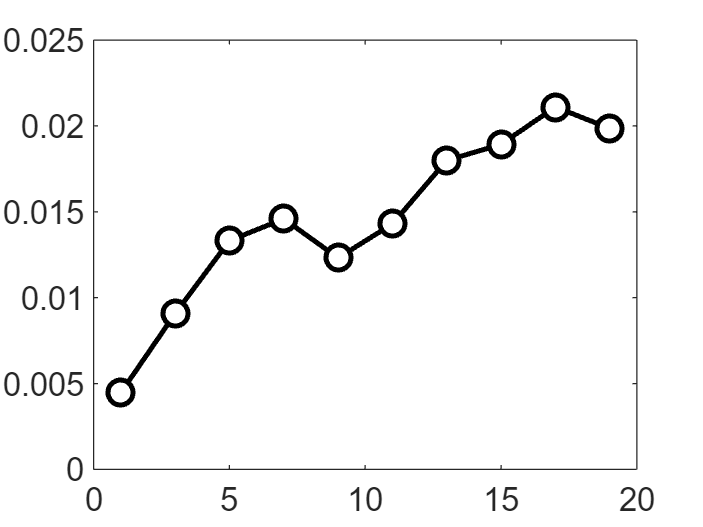

A_mp = removeBG_func(B,T_opt_mp,Tb_opt_mp,Q);
% data from the first 'Tb_opt_mp' time points are invalid

[Cmp,Cmp_eta,N_eta,n_eta] = correlationMPmicro_func(A_mp(Tb_opt_mp:end),B(Tb_opt_mp:end),7);
C_mp = correlationMP_func(A_mp(Tb_opt_mp:end),B(Tb_opt_mp:end),tg);

% figure()
% plot(C_mp,'-o')

C_mp_smooth = smooth(C_mp,3);
x = 1 : length(C_mp_smooth);
x_plot = 1: 2 :length(C_mp_smooth)-2;
figure()
plot(x(x_plot), C_mp_smooth(x_plot),'-o','color','#5E81AC','LineWidth',2,'MarkerSize',10,'MarkerFaceColor','auto')
xticks(1:4:20)
xlim([0 18])
ylim([0 0.025])
% xlabel('$t$','Interpreter','latex')
% ylabel('$\tilde{C}_{mp}(t)$','Interpreter','latex','Rotation',0)
set(gca, fontsize=fontsize)

## Compute a new time series after removing background fluctuations

% [Input] S, T, Tb, Q
% S [N*1 column vector]: Original time series (e.g., return time series, sentiment index series)
% T [numeric]: Time window
% Tb [numeric]: Time window (Within this time window Tb, the dynamic system is in a quasi-steady state)
% Q [0/1 value]: Intrinsic drivers
%    Q = 1: for discussing intrinsic forces driving the dynamic system, such as the volatility.
%    Q = 0: for discussing external information driving the dynamic system, such as the sentiment index.

% [Output] Srbg
% Srbg [N*1 column vector]: The new time series after removing background fluctuations


function Srbg = removeBG_func(S,T,Tb,Q)

switch Q
    case 0 % External information drivers
        for t = Tb:length(S)
            STb(t,1) = mean( S(t-Tb+1:t) ); % data from the first Tb time points are invalid
        end
        for t = T:length(S)
            ST(t,1) = mean( S(t-T+1:t) );  % data from the first T time points are invalid
        end

    case 1 % Intrinsic drivers
        for t = Tb:length(S)
            STb(t,1) = std( S(t-Tb+1:t) );  % data from the first Tb time points are invalid
        end
        for t = T:length(S)
            ST(t,1) = std( S(t-T+1:t) );  % data from the first T time points are invalid
        end
end

Srbg = ST - STb;
end

## Compute the multi-point correlation function

% [Input] A, B, tg
% A [N*1 column vector]: Time series A (e.g., volatility series after removing background fluctuations)
% B [N*1 column vector]: Time series B (e.g., return series)
% tg [numeric]: Length of multi-point correlation function

% [Output] Cmp
% Cmp [tg*1 column vector]: The correlation function Cmp

function Cmp = correlationMP_func(A,B,tg)

A_sgn = sign(A);

for t = 1:tg % t refers to the correlation considering t days
    S_sgn = zeros(length(A),1);
    for tn = t:length(S_sgn)-1    % tn refers to the tn-th data point in the time series
        S = sum( A_sgn(tn-t+1:tn) );
        if S == 0
            S = 1;
        else
        end
        S_sgn(tn) = sign( S ); % S is the multi-point time fluctuation, and for simplicity, the sign is used for calculation
    end
    Cmp(t,1) = mean( S_sgn(t:end-1).*B(t+1:end) ) - mean( S_sgn(t:end-1) )*mean( B(t+1:end) );
end
end


## [function] Compute multi-point correlation function for micro-state configurations

% [Input] A, B, tg
% A [N*1 column vector]: Time series A (e.g., volatility series after removing background fluctuations)
% B [N*1 column vector]: Time series B (e.g., return series)
% tg [numeric]: Length of multi-point correlation function

% [Output] Cmp,Cmp_eta,N_eta,n_eta
% Cmp [numeric]: The computed correlation function for a given tg.
% Cmp_eta [(tg+1)×1 column vector]: Time correlation function between the sum of sign(A) and B, 
%                                   evaluated for different values of η. Here, η represents a class of 
%                                   past configurations that sum(sign(A)) belongs to.
% N_eta [(tg+1)×1 column vector]: The number of data points where sum(sign(A)) equals η.
% n_eta [(tg+1)×1 column vector]: The proportion (ratio) of data points where sum(sign(A)) equals η.

function  [Cmp,Cmp_eta,N_eta,n_eta] = correlationMPmicro_func(A,B,tg)

Cmp_eta = zeros(tg+1,1);
N_eta = zeros(tg+1,1);

for i = tg:length(A)-1
    v_sum_sign(i) = sign(sum(sign(A(i-tg+1:i))));
    v_positive_num = length(find(sign(A(i-tg+1:i))>0));

    if v_sum_sign(i)==0
        v_sum_sign(i)=1;
    end
    Cmp_eta(v_positive_num+1) = Cmp_eta(v_positive_num+1) + v_sum_sign(i)*B(i+1);
    N_eta(v_positive_num+1) = N_eta(v_positive_num+1) + 1;
end
N = sum(N_eta);
n_eta = N_eta/N;

B_mean = mean(B(tg+1:end));
eta = -tg:2:tg;
for j = 1:length(Cmp_eta)
    Cmp_eta(j) = Cmp_eta(j)/N - (sum(sign(eta(j))*N_eta(j))/N)*B_mean;
end
Cmp = sum(Cmp_eta);

end

## [Function] Filter effective time window pairs and optimal time window pair using the multi-point correlation function

% [Input] A, B, Q, T_para, tg
% B [N*1 column vector]: Dynamic system variable (e.g., returns)
% A [N*1 column vector]: Dynamical quantity driving the system (e.g., volatility, sentiment index)
% Q [0/1 value]: Intrinsic drivers
%    Q = 1: A is the intrinsic driving force of the dynamic system, such as the volatility.
%    Q = 0: A is the external information driving force of the dynamic system, such as the sentiment index.
% T_para = [T_start, T_step, T_stop, Tb_start, Tb_step, Tb_stop]: Parameters for time window traversal
% tg [numeric]: Length of multi-point correlation function

% [Output] AP0, Am, num, T_opt, Tb_opt
% AP0 [T_stop*Tb_stop matrix]: Effective correlation strength
% Am [numeric]: Correlation strength under the optimal time windows
% num [numeric]: Number of the effective time window pairs
% T_opt [numeric], Tb_opt [numeric]: Optimal time window pairs

% In this function, t1 and t2 are adjustable parameters. 
% They can be modified according to the specific situation.
% In this case, t1 = 5 and t2 = 10.

function [AP0,Am,num,T_opt,Tb_opt] = window_selection_MP_func(A,B,Q,T_para,tg)

t1 = tg/2;
t2 = tg;

T_start = T_para(1);
T_step = T_para(2);
T_stop = T_para(3);
Tb_start = T_para(4);
Tb_step = T_para(5);
Tb_stop =T_para(6);

for T = T_start:T_step:T_stop
    for Tb = Tb_start:Tb_step:Tb_stop
        % step 1: Calculate the correlation function
        A_ = [];
        if Q == 1
            A_ = removeBG_func(B,T,Tb,Q);
        else
            A_ = removeBG_func(A,T,Tb,Q);
        end
        C = correlationMP_func( A_(T_stop+Tb_stop:end),B(T_stop+Tb_stop:end),tg ); 
        % For consistency, it is recommended to remove the first T_stop+Tb_stop data points from all data, 
        % so that when selecting the optimal window, the length of all valid data is consistent.
        SC = smooth(C ,3); % Parameter 3 represents smoothing with a 3-point window

        % step 2: Find the first sign-changing point t0
        t0 = 1;
        while sign(SC(t0)) == sign(SC(1))
            t0 = t0+1;
            if t0 > length(SC)
                break
            end
        end

        % step 3: Divide the correlation function into two parts based on t1 and t2
        P1 = SC(1:t1);
        AP1 = mean( abs(P1) );
        P2 = SC(t1+1:t2);
        AP2 = mean( abs(P2) );
        
        % step 4: Compute AP0
        if t0 > t2 && all(abs(P1) < AP2) && all(abs(P2) > AP1)
            AP0(T,Tb) = mean( SC(1:t2) );
        else
            AP0(T,Tb) = 0;
        end
    end
end

% step 5: Count the number of valid time windows
num = length( find(AP0~=0) );
aAP0 = abs(AP0);
[T_opt,Tb_opt] = find( aAP0==max(max(aAP0)) );
T_opt = T_opt(1);
Tb_opt = Tb_opt(1);
Am = AP0(T_opt,Tb_opt);
end
